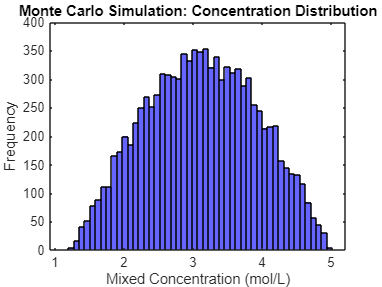

% Define the ranges for flow rates and concentrations
F1_min = 0.001; F1_max = 0.006;  % Flow rate range for stream 1 (L/s)
F2_min = 0.001; F2_max = 0.006;  % Flow rate range for stream 2 (L/s)
C1_min = 1.5; C1_max = 5;   % Concentration range for stream 1 (mol/L)
C2_min = 1; C2_max = 5;   % Concentration range for stream 2 (mol/L)

% Number of simulations
n_simulations = 10000;

% Generate random samples for flow rates and concentrations
F1_samples = F1_min + (F1_max - F1_min) * rand(n_simulations, 1);
F2_samples = F2_min + (F2_max - F2_min) * rand(n_simulations, 1);
C1_samples = C1_min + (C1_max - C1_min) * rand(n_simulations, 1);
C2_samples = C2_min + (C2_max - C2_min) * rand(n_simulations, 1);

% Calculate the concentration for each sample
C_mix_samples = (F1_samples .* C1_samples + F2_samples .* C2_samples) ./ (F1_samples + F2_samples);

% Plot the distribution of mixed concentrations
figure;
histogram(C_mix_samples, 50, 'FaceColor', 'blue', 'EdgeColor', 'black');
title('Monte Carlo Simulation: Concentration Distribution');
xlabel('Concentration (mol/L)');
ylabel('Frequency');


% Calculate and display statistics
mean_C_mix = mean(C_mix_samples);
std_C_mix = std(C_mix_samples);

fprintf('Mean mixed concentration: %.2f mol/L\n', mean_C_mix);

Mean mixed concentration: 3.13 mol/L


fprintf('Standard deviation: %.2f mol/L\n', std_C_mix);

Standard deviation: 0.80 mol/L
